# MEG data

adults = 1

if adults~=1
    % Children
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\9001'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\3448' % 2810 % Found channel 183
    %
    %meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\Excluded No Sound\2724' % 2724
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\Excluded No Sound\2810' % 2724
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\9001'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2739'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\3402'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\3416'
    ref_chans       = 126:128 % 124:128   % Supposedly 125-127
    audio_ch        = 135; % Audio event from fOMRI = 135 + 1  
    every_trigger   = 145  % spikes every event (every 500ms)
    trig_chans      = 146:152 % 7-tone

    unknown_chans   = 179:185 % Shouldn't be anything here

    other_ch        = 192  % Unsure what this is, roughly is on/off while any event is occurring


elseif adults == 1
    % Adults
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\9000\' % Jordan trial  
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\2744' % 2810   
    %meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\Errors\Other Errors\No Sound\2552'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\Errors\Other Errors\No Sound\2689'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\2552'
    meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\9021'
    
    ref_chans  = 159:169   % Supposedly 160-162    
    audio_ch = 167;        % Audio event from fOMRI = 166 + 1  
    every_trigger = 193;   % spikes every event (every 500ms)
    trig_chans = 194:204   % 11 tones
    trig_chans = 194:200   % 7-tone
    other_ch   = 256       % Unsure what this is, roughly is on/off while any event is occurring    

end

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\9000\'

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\2744'

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\Errors\Other Errors\No Sound\2689'

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\2552'

meg_path = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\9021'

ref_chans =    159   160   161   162   163   164   165   166   167   168   169


trig_chans =    194   195   196   197   198   199   200   201   202   203   204


trig_chans =    194   195   196   197   198   199   200


other_ch = 256




cd(meg_path)
if adults == 1
    all_cons = dir('*tspca.con');
    %all_cons = dir('*Device14_tspca.con') % Test latency on other devices
else
    all_cons = dir('*rethm_tspca.con');
    if length(all_cons) == 0
        all_cons = dir('*denoise_rethm.con');
    end
end

all_cons = 2×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


% if length(all_cons) == 0
%     if adult == 1
%         all_cons = dir('*B3.con'); # Usually named as such
%     elseif adult == 0
%         all_cons = dir('*B1.con');
%     end
% end
if length(all_cons) == 0
    all_cons = dir('*.con');
end
if length(all_cons) == 0
    disp("NO CON FILE FOUND")
end

all_cons_table = struct2table(all_cons); % convert the struct array to a table
all_cons_by_size = sortrows(all_cons_table, 'bytes', 'descend'); % sort the table by 'size', as 15 min roving oddball size will be larger than 10 min resting state
all_cons_by_size = table2struct(all_cons_by_size);
confile = all_cons_by_size;    % Gets first one somehow
[file] = confile(1)

file = struct with fields:
       name: '9021_SOUND_TEST_Both_Adult_SpeakerCentred_Device14_tspca.con'
     folder: 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Adult_MEG\9021'
       date: '14-Mar-2022 11:17:52'
      bytes: 122947292
      isdir: 0
    datenum: 7.3859e+05


pathname = file.folder;
filename = file.name;     
meg_file = filename

meg_file = '9021_SOUND_TEST_Both_Adult_SpeakerCentred_Device14_tspca.con'

% chan_analog = 192; % Unknown information in this channel (result usually 0, occasionally 5) 
% % See meetings
% %trig_chans = 129:134 # Noise category A
% %trig_chans = 136:144 # noise category A
% %trig_chans = 145:152 # noise category B
% %trig_chans = 153:159 # noise category A
% %trig_chans = [184 185 186];

% %% Save information as to which tones were played as a text file 


% dataset = fullfile(meg_path, meg_file);
% event_meg = ft_read_event(dataset, 'dataformat','yokogawa_con', 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up');% , ); % , 
% event_meg = orderfields(event_meg,{'value', 'sample', 'type', 'offset', 'duration'}); % re-order columns
% fields_to_delete = {'offset', 'duration'};
% event_meg = rmfield(event_meg,fields_to_delete);
% n=numel(event_meg);
% for k=1:n
%     event_meg(k).type = str2num(event_meg(k).type) -trig_chans(1) +1;
% end
% 
% N = numel(event_meg) 
% oldnames = {'value','sample','type'};
% newnames = {'sound_played','time_ms','tone_number'};
% for k=1:length(oldnames)
%   [event_meg(1:N).(newnames{k})] = deal(event_meg.(oldnames{k})) ;
% end
% event_meg = rmfield(event_meg,oldnames);
% save event_meg event_meg
% writetable(struct2table(event_meg), 'event_meg.txt')
% %%

dataset = fullfile(meg_path, meg_file);
hdr = ft_read_header(dataset);

% Read output from fieldtrip
data = ft_read_data(dataset)

data =     0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000         0   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000  

% % Read output from MNE
% data = ft_read_data('E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\2872_CM_ME125_2018_01_12_B1_denoise_rethm_raw_tsss.fif')

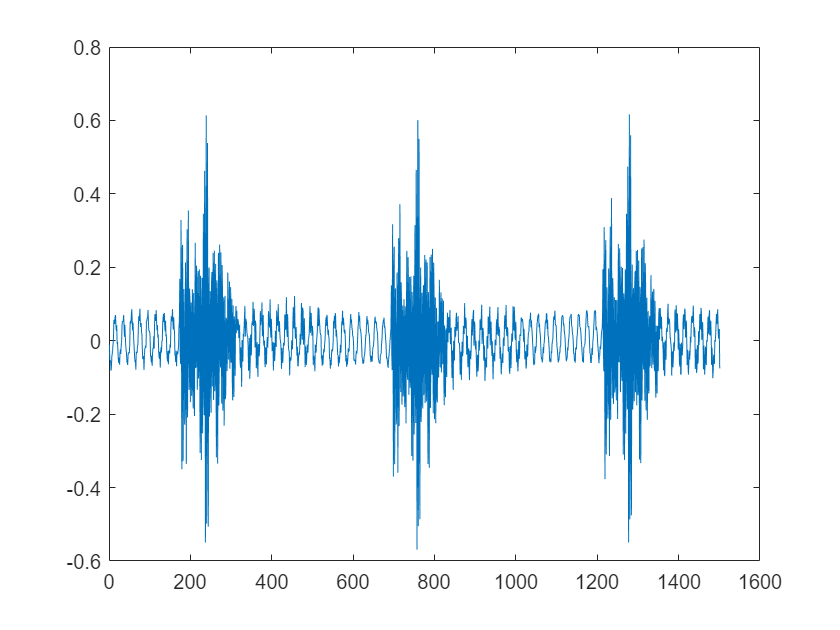

% Examine audio bit
duration = 1.5;
start_secs = 45;
end_secs = start_secs + duration;
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', audio_ch);
plot(dat)

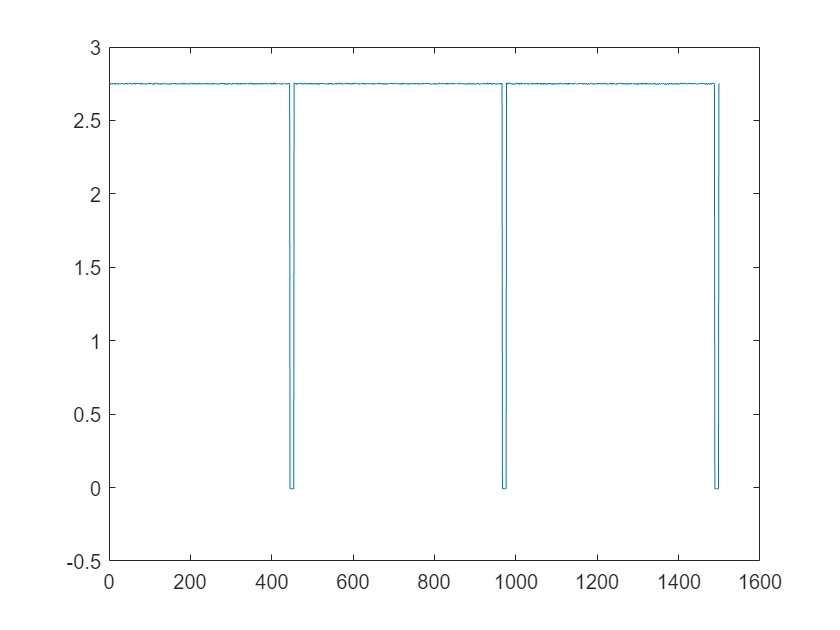

% Examine every trigger bit
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', every_trigger);
plot(dat)

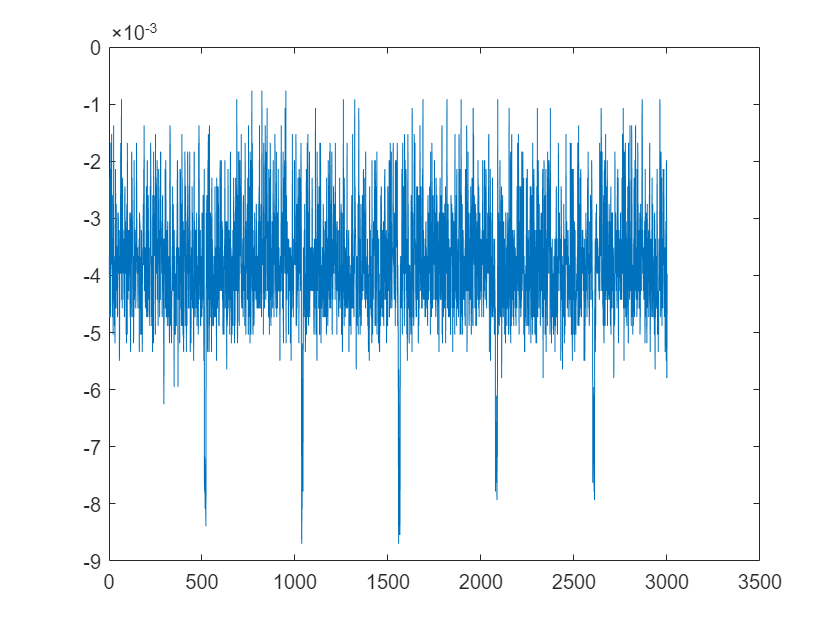

% Examine data from first trigger channel
dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', trig_chans(1));
plot(dat)

% % Examine a piece of data
% dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', other_ch);
% plot(dat)

% Plot ref channels
start_plotting = start_secs*1000 % 25 secs in is when data normally begins
for chan_num = ref_chans 
    for plot_length = [100] % [2 5] % [100] % [30 10] % Various lengths in secs
        disp(strcat(num2str(chan_num), " , ", num2str(plot_length)))
            % At the lowest zoom level, 
        figure;
        plot(data(chan_num,start_plotting:(start_plotting+plot_length*1000)));
    end
end
% -> % Unsure what chan_analog is, using audio_ch
% the low and high signal are most easily visible
% Halfway between high and low is a good threshold for detecting the event

% IF YOU CANNOT FIND ANYTHING
% Plot all (non-data) channels
start_plotting = start_secs*1000 % 25 secs in is when data normally begins
for chan_num = 126:256
    for plot_length = [100] % [2 5] % [100] % [30 10] % Various lengths in secs
        disp(strcat(num2str(chan_num), " , ", num2str(plot_length)))
            % At the lowest zoom level, 
        figure;
        plot(data(chan_num,start_plotting:(start_plotting+plot_length*1000)));
    end
end
% -> % Unsure what chan_analog is, using audio_ch
% the low and high signal are most easily visible
% Halfway between high and low is a good threshold for detecting the event

% % Plot trigger channels
% start_plotting = start_secs*1000 % 25 secs in is when data normally begins
% for chan_num = trigger_chans % unknown_chans % [audio_ch,chan_analog] 
%     for plot_length = [100] % [2 5] % [100] % [30 10] % Various lengths in secs
%         disp(strcat(num2str(chan_num), " , ", num2str(plot_length)))
%             % At the lowest zoom level, 
%         figure;
%         plot(data(chan_num,start_plotting:(start_plotting+plot_length*1000)));
%     end
% end
% % -> % Unsure what chan_analog is, using audio_ch
% % the low and high signal are most easily visible
% % Halfway between high and low is a good threshold for detecting the event

event = ft_read_event(dataset, 'dataformat','yokogawa_con', 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up')% , ); % , 

smp = [event.sample];
typ = {event.type};
val = [event.value];
%You can plot the events in a scatter plot. Along the horizontal axis is time, vertical is the value.
figure
plot(smp/hdr.Fs, val, '.');

## Basic preprocessing

% From ME125 - Phase 2 - Step 1

cfg                         = [];
cfg.dataset                 = dataset;
cfg.headerfile              = dataset;
cfg.datafile                = dataset;
cfg.trialfun                = 'ft_trialfun_general';  

cfg.channel                 = hdr.grad.label; 
%cfg.channel                = 'AG*';
%cfg.channel                = '161'; % 19*'; %chan_analog
%cfg.channel                = 'all'
%cfg.channel                = 'TRIG*'

cfg.continuous              = 'yes';

%highpass filter
cfg.hpfilter                = 'yes';
cfg.hpfiltwintype           = 'blackman';
cfg.hpfilttype              = 'firws';          %'but'  'firws'
cfg.hpfiltdir               = 'onepass-zerophase';
cfg.hpfreq                  = 0.1;              %FIXME should try something lower to appease reviewers 0.1
cfg.hpfiltdf                = 0.15;             % highpass transition width
%cfg.hpfiltord               = 6;                % highpass filter order
cfg.dftfreq                 = 50;               % removal line noise

data                        = ft_preprocessing(cfg);

%lowpass filter
cfg                         = [];
cfg.lpfilter                = 'yes';
cfg.lpfilttype              = 'firws';              %'but'  'firws'
cfg.lpfiltwintype           = 'blackman';           % lowpass window type, 'hann' or 'hamming' (default) or 'blackman' or 'kaiser' (firws)
cfg.lpfiltdir               = 'onepass-zerophase';  % filter direction, 'twopass' (default), 'onepass' or 'onepass-reverse' or 'onepass-zerophase' (default for firws) or 'onepass-minphase' (firws, non-linear!)
cfg.lpfreq                  = 30;
cfg.lpfiltdf                = 10;

%band stop filter
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [49.5 50.5];

data                        = ft_preprocessing(cfg,data); 

% % Lance - Optional?
% events = load("F:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Child_MEG\2872\event.mat")
% cfg.trialdef.eventtype = event.type
% cfg.trialdef.eventvalue = event.value
% % cfg.trialdef.eventtype  = 'analogtrig'; % use 'trial' for Yokogawa data
% % cfg.trialdef.eventvalue = [184 185 186];
% cfg.trialdef.prestim = 0.1
% cfg.trialdef.poststim = 0.4
% % cfg.trigindx = 146 ^ 192
% % cfg = ft_definetrial(cfg);
% data = ft_preprocessing(cfg);

% Convert a fieldtrip object to an MNE object
%fiff_file  = 'E:\BigData\MEG\MRES\ME125_MMN_phase1_Yanan\Lance_MEG\P00\FieldTrip data MAT to MNE data FIF.fif'
fiff_file  =  strcat(meg_path,'FieldTrip data MAT to MNE data FIF.fif')
fieldtrip2fiff(fiff_file, data)

%% Display waveforms using ft_databrowser
cfg = [];
cfg.blocksize = 10;
cfg = ft_databrowser(cfg, data);

% Scan other channels, plot those channels with things detected
events = struct('channel', num2cell(trig_chans))
cutoff_num_events = 100
for chan = trig_chans
    disp(chan)
    event = ft_read_event(dataset,'threshold', 1.6, 'chanindx', chan, 'detectflank', 'up')  % No triggers detected, we are below threshold
    %event = ft_read_event(dataset,'threshold', 0.1, 'chanindx', chan, 'detectflank', 'up')  % No triggers detected, we are below threshold
       
    events(chan).channel = event;
    length_structure = structfun(@(field) length(field),events(chan));
    if length_structure > cutoff_num_events;
        disp(strcat("Channel: ", num2str(chan), " events: ", num2str(length_structure)))
        dat = ft_read_data(dataset, 'begsample', start_secs*1000, 'endsample', end_secs*1000, 'chanindx', chan);
        plot(dat)
    end
end

% Scan known channel
event = ft_read_event(dataset, 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up')

table = struct2table(event);
table(1:14,:)

%Examine a dat piece - more complex, for if triggers are defined properly
dataset = fullfile(meg_path, meg_file);
hdr   = ft_read_header(dataset);

cfg =[];
cfg.dataset                 = dataset;
cfg.headerfile              = dataset;
cfg.datafile                = dataset;
cfg.trialfun                = 'ft_trialfun_general'; 

% Multiple channels
cfg.channel                 = hdr.grad.label; 
%cfg.channel                = 'AG*';
%cfg.channel                = '135' % audio_ch % '161'; % 19*'; %chan_analog
%cfg.channel                = 'all'
%cfg.channel                = 'TRIG*'

%highpass filter
cfg.hpfilter                = 'yes';
cfg.hpfiltwintype           = 'blackman';
cfg.hpfilttype              = 'firws';          %'but'  'firws'
cfg.hpfiltdir               = 'onepass-zerophase';
cfg.hpfreq                  = 0.1;              %FIXME should try something lower to appease reviewers 0.1
cfg.hpfiltdf                = 0.15;             % highpass transition width
%cfg.hpfiltord               = 6;                % highpass filter order
cfg.dftfreq                 = 50;               % removal line noise

data                        = ft_preprocessing(cfg,data);

%lowpass filter
cfg                         = [];
cfg.lpfilter                = 'yes';
cfg.lpfilttype              = 'firws';              %'but'  'firws'
cfg.lpfiltwintype           = 'blackman';           % lowpass window type, 'hann' or 'hamming' (default) or 'blackman' or 'kaiser' (firws)
cfg.lpfiltdir               = 'onepass-zerophase';  % filter direction, 'twopass' (default), 'onepass' or 'onepass-reverse' or 'onepass-zerophase' (default for firws) or 'onepass-minphase' (firws, non-linear!)
cfg.lpfreq                  = 30;
cfg.lpfiltdf                = 10;

%band stop filter
cfg.headerfile              = dataset;
cfg.trialfun                = 'ft_trialfun_general'; 
cfg.bsfilter                = 'yes';
cfg.bsfreq                  = [49.5 50.5];
data                        = ft_preprocessing(cfg,data);



event = ft_read_event(dataset, 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up'); % 166 % 'trigindx', audio_ch

trl = [];

cfg.trialdef.eventtype = event.type;
% cfg.trialdef.eventtype  = 'analogtrig'; % use 'trial' for Yokogawa data
cfg.trialdef.eventvalue = event.value;
% cfg.trialdef.eventvalue = 1;
cfg.trialdef.prestim = 0.1;
cfg.trialdef.poststim = 0.4;
cfg.trigindx = trig_chans % audio_ch % 'chanindx' % audio_ch audio_ch ^ 192
cfg = ft_definetrial(cfg);

for i=1:length(event)
if strcmp(event(i).type, cfg.trialdef.eventtype)
  % it is a trigger, see whether it has the right value
  if ismember(event(i).value, cfg.trialdef.eventvalue)
    % add this to the trl definition
    begsample     = event(i).sample - cfg.trialdef.prestim*hdr.Fs;
    endsample     = event(i).sample + cfg.trialdef.poststim*hdr.Fs - 1;
    offset        = -cfg.trialdef.prestim*hdr.Fs;
    trigger       = event(i).value; % remember the trigger (=condition) for each trial
    if isempty(trl)
      prevtrigger = nan;
    else
      prevtrigger   = trl(end, 4); % the condition of the previous trial
    end
    trl(end+1, :) = [round([begsample endsample offset])  trigger prevtrigger];
  end
end
end

% %Filter
% 
% %Delete non-beeps
% for i = length(data.trialinfo):-1:1
%   data.trialinfo(i).latency = data.trialinfo(i).latency+12; 
%  
%    if strcmp(strtok(data.trialinfo(i).type, 'N'), 'DI') ~= 1
%       data.trialinfo(i) = []; 
%    else
%         [~, trigger]  = strtok(data.trialinfo(i).type, 'N'); % remember the trigger (=condition) for each trial
%         trigger = str2double(trigger(2));
%         data.trialinfo(i).tone = trigger;
%    end
% end

function [trl, event] = mytrialfun(cfg)

% read the header information (including the sampling rate) and the events from the data
hdr   = ft_read_header(cfg.dataset);
event = ft_read_event(cfg.dataset, 'threshold', 1.6, 'chanindx', trig_chans, 'detectflank', 'up');

% search for "trigger" events according to 'trigchannel' defined outside the function
value  = [event(find(strcmp(cfg.trialdef.trigchannel, {event.type}))).value]';
sample = [event(find(strcmp(cfg.trialdef.trigchannel, {event.type}))).sample]';

% creating your own trialdefinition based upon the events
trl = [];
for j = 1:length(value);
  trlbegin = sample(j) - round(cfg.trialdef.prestim  * hdr.Fs);
  trlend   = sample(j) + round(cfg.trialdef.poststim * hdr.Fs);
  offset   = -round(cfg.trialdef.prestim  * hdr.Fs);
  newtrl   = [ trlbegin trlend offset];
  trl      = [ trl ; newtrl];
end
end